# **FDS 2024: Field and service robotics**

## `Homework 1 Question 4`

## Andrea Morghen

To run this code the **Statistics and Machine Learning Toolbox is required. **( the function knnsearch is a very usefull function since it deals with the identification of the nearest point in a single line!. However this task could have been implemented with different lines of code without this function)

First of all lets import the matrix map

clc 
clear 
load image_map.mat

the map is composed of 0 and 1,in order to plot the complete enviroment lets define the initial and final points. The starting point qi is represented as a red dot and the final goal qf is represented as a star.

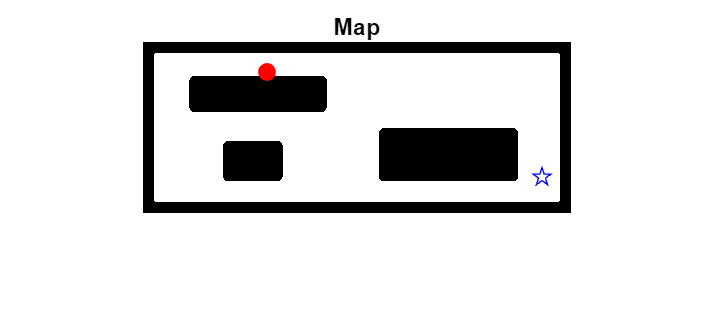

qi=[30 125];
qf=[135 400];
image_map=double(image_map);

imshow(image_map)
title('Map');
hold on
scatter(qi(2),qi(1),400,'red','.');
scatter(qf(2),qf(1),50,'blue','pentagram');

**RRT implementation and Map Plot **

imshow(image_map);
title('Final Map with tree');
hold on
scatter(qi(2),qi(1),400,'red','.');
scatter(qf(2),qf(1),50,'blue','pentagram');

Let's define some useful parameters for the RRT algoritm

n_exec=150;
delta=20;
goal_reached = false;
qlist = [qi]; 
iteration=0;

This is the algoritm for the RRT, it ends when either the count variable reaches its maximum value, either the goal is reached 

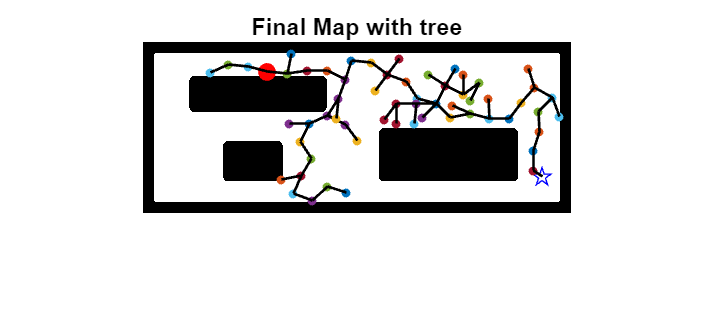

while (iteration<n_exec && goal_reached == false)
    iteration=iteration+1;

    qrand=[randi(size(image_map,1)),randi(size(image_map,2))];
    qnear=qlist(knnsearch(qlist,qrand),:);
    direction= atan2(qrand(1)-qnear(1),qrand(2)-qnear(2));
    qnew=qnear+round([sin(direction),cos(direction)]*delta);

    % connection between qnear and qnew
    line = round([linspace(qnear(1), qnew(1)); linspace(qnear(2), qnew(2))]);
 
    %collision detection
    coll = false; 
    for i = 1:size(line, 2)
        if image_map(line(1, i), line(2, i)) == 0
            coll = true;
            break; 
        end
    end

    %add point to the list
    if ~coll
        qlist = [qlist; qnew]; 
        plot(qnew(2), qnew(1), '.', 'MarkerSize', 10); 
        plot([qnear(2), qnew(2)], [qnear(1), qnew(1)], 'k', 'LineWidth', 1); 
    end

    %check for qf distance  
    if norm(qf-qnear,2) <= delta
        % connection between qnear and qnew
        line = round([linspace(qnear(1), qf(1)); linspace(qnear(2), qf(2))]);
     
        %collision detection
        coll = false; 
        for i = 1:size(line, 2)
            if image_map(line(1, i), line(2, i)) == 0
                coll = true;
                break; 
            end
        end
    
        %add point to the list
        if ~coll
            qlist = [qlist; qf]; 
            plot([qnear(2), qf(2)], [qnear(1), qf(1)], 'k', 'LineWidth', 1); 
            goal_reached=true;  
        end

    else
        goal_reached=false;
    end
end

if goal_reached
phrase = sprintf('Goal reached in %i iteration', iteration);
disp(phrase);
else
phrase = sprintf('Goal was not reached within %i iteration', n_exec);
disp(phrase);
end

Goal reached in 113 iteration
